## Plot Path

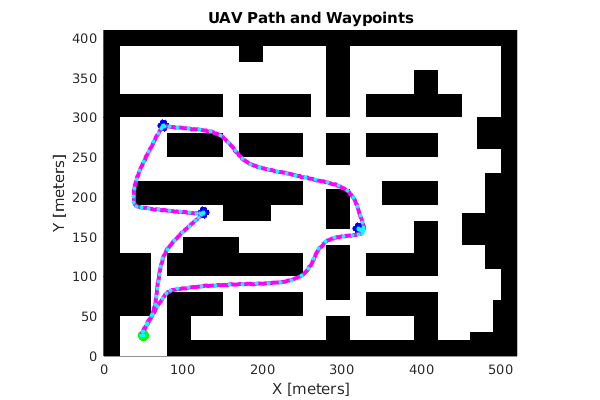

ans = 19.5615

%load map.mat;

f1 = figure(1); clf;
hold on;
show(map);
plot(position.gps.Data(1,1), position.gps.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8, "DisplayName", "start");
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'bo', 'LineWidth', 3, "DisplayName", "waypoint"); 
end
%plot(pos_actual.Data(:,1), pos_actual.Data(:,2), 'linewidth', 6);
plot(position.true.Data(:,1), position.true.Data(:,2), 'm', 'linewidth', 3, "DisplayName", "actual");
if ~any(stop_codes.Data(:,find(strcmp(stop_code_tb.description, 'success'))))
    plot(position.gps.Data(end, 1), position.gps.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3, "DisplayName", "crash");
end
if any(stop_codes.Data(:,find(strcmp(stop_code_tb.description, 'success'))))
    plot(position.gps.Data(end, 1), position.gps.Data(end, 2), 'g^', 'markersize', 14, 'LineWidth', 3, "DisplayName", "success");
end
scatter(trajectory.x_ref_points(:,2), trajectory.y_ref_points(:,2), 10, 'cyan', 'filled', "DisplayName", "reference");
% fault_pos = getsampleusingtime(position.gps, 180).Data(1:2);
% plot(fault_pos(1), fault_pos(2), 'kx', 'markersize', 15, 'LineWidth', 3, 'DisplayName', 'Fault Occured');
% fault_pos = getsampleusingtime(position.gps, 191).Data(1:2);
% plot(fault_pos(1), fault_pos(2), 'gx', 'markersize', 9, 'LineWidth', 3, 'DisplayName', 'Fault Detected');
hold off;
title("UAV Path and Waypoints");sim_params.perf_param_thresh.min_v 

%legend('Location',"best");

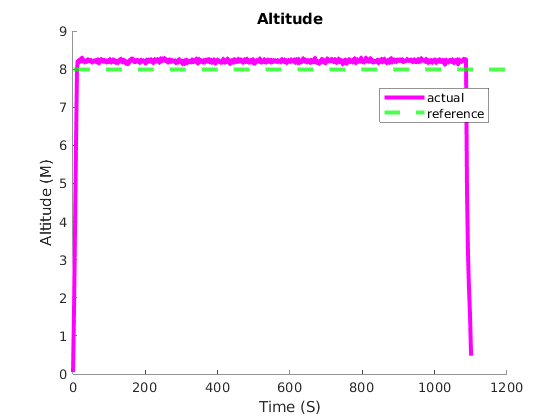


f6 = figure(6); clf;
hold on;
plot(position.true.Time, position.true.Data(:,3), 'm', 'linewidth', 3, "DisplayName", "actual");
yline(sim_params.z_ref, 'g--', 'linewidth', 3, 'DisplayName', 'reference');
hold off;
legend(location='best');
title("Altitude");
xlabel('Time (S)');
ylabel('Altitude (M)');

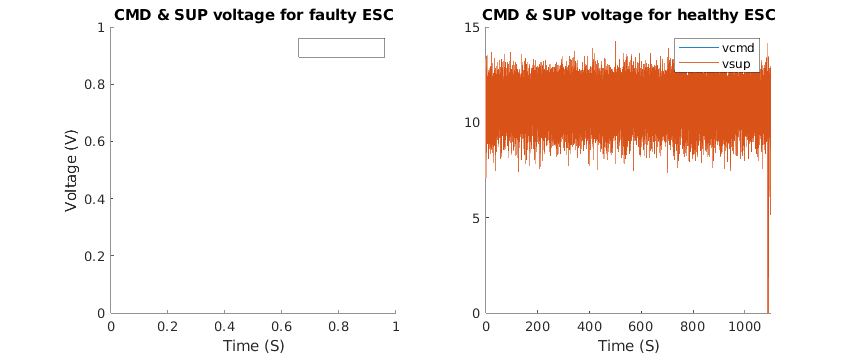


f9 = figure(9); clf;
f9.Position = [0 0 1200 500];
subplot(1,2,1);
hold on;
idx = find(any(escs.esc_faults.Data), 1);
if any(idx)
    plot(escs.vcmd.Time, escs.vcmd.Data(:,idx), 'displayname', 'vcmd');
    plot(escs.vcmd.Time, escs.vsup.Data(:,idx), 'displayname', 'vsup');
end
hold off;

legend;
title('CMD & SUP voltage for faulty ESC')
ylabel('Voltage (V)');
xlabel('Time (S)');

subplot(1,2,2);
hold on;
idx = find(~any(escs.esc_faults.Data), 1);
plot(escs.vcmd.Time, escs.vcmd.Data(:,idx), 'displayname', 'vcmd');
plot(escs.vcmd.Time, escs.vsup.Data(:,idx), 'displayname', 'vsup');
hold off;
title('CMD & SUP voltage for healthy ESC')
xlabel('Time (S)');
legend;

## Euclidean Position Error

avgposerr = mean(errors.euclidean_pos_err.Data)

avgposerr = 0.7954

varposerr = var(errors.euclidean_pos_err.Data)

varposerr = 0.2171

mean(errors.var_pos_err.Data)

ans = 0.0621

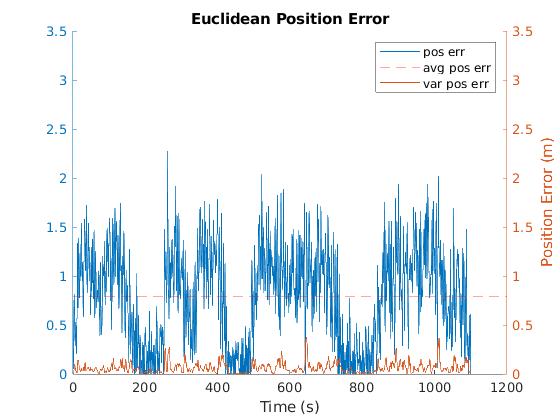

f8 = figure(8); clf;
hold on;
yyaxis left;
ylim([0 3.5]);
plot(errors.euclidean_pos_err.Time, errors.euclidean_pos_err.Data, 'DisplayName', 'pos err');
yline(avgposerr, 'r--', 'DisplayName', 'avg pos err');
yyaxis right;
ylim([0 3.5]);
plot(errors.var_pos_err.Time, errors.var_pos_err.Data, 'DisplayName', 'var pos err')
hold off;
legend;
title('Euclidean Position Error');
xlabel("Time (s)");
ylabel("Position Error (m)");

## Voltage and SOC Plot

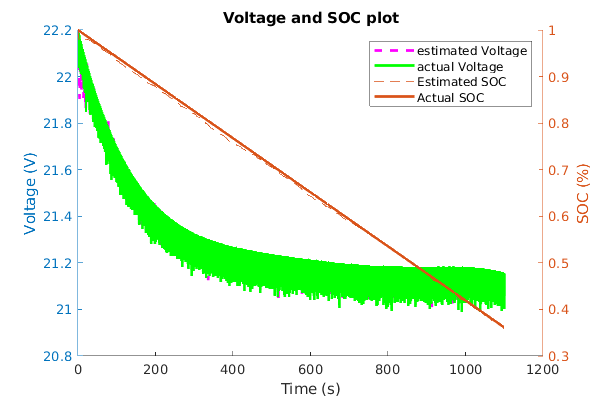

f3 = figure(3); clf;
f3.Position = [0 0 600 400];
yyaxis left;
hold on;
plot(battery.battery_hat.v.Time(:), battery.battery_hat.v.Data(:,1), 'm--', 'linewidth', 2, "DisplayName", "estimated Voltage");
plot(battery.battery_true.v.Time(:), battery.battery_true.v.Data(:,1), 'g-', 'linewidth', 2, "DisplayName", "actual Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;

plot(battery.battery_hat.z.Time(:), battery.battery_hat.z.Data(:), '--', "DisplayName", "Estimated SOC");

plot(battery.battery_true.z.Time(:), battery.battery_true.z.Data(:),'-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
title('Voltage and SOC plot');
xlabel("Time (s)");
ylabel("SOC (%)");
%xlim([500 550]);
legend();

## Current Plot

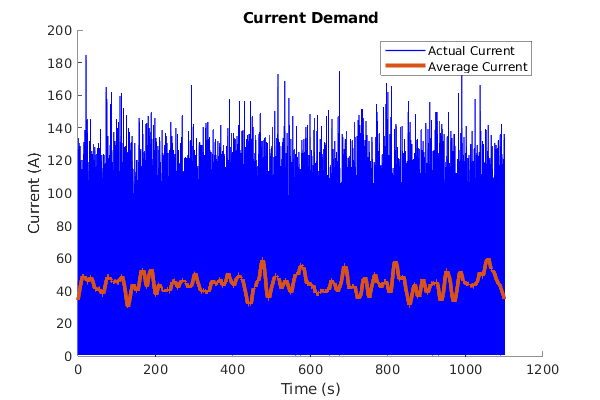

f4 = figure(4); clf;
f4.Position = [0 0 600 400];
hold on;
plot(battery.battery_true.i.Time(:), battery.battery_true.i.Data(:), 'b', 'linewidth', 1, "DisplayName", "Actual Current");
plot(downsample(battery.battery_true.i.Time(:), 20),smoothdata(downsample(battery.battery_true.i.Data(:), 20), 'rlowess', 50), 'linewidth', 3, "DisplayName", "Average Current");
hold off;
title('Current Demand');
xlabel("Time (s)");
ylabel("Current (A)");
legend();